# Parametric Curves 

A more general representation of a curve involves expressing its coordinates in terms of another independent variable or parameter as follows


$$x = f(u), y = g(u), u \in [a,b]$$


Each value of u corresponds to a coordinate pair (f(u), g(u)). If we collect all the points defined by u in a specific interval, we get a parametric curve. For example, the definition


$$x = \cos u, y = \sin u, u \in [0, 2 \pi]$$


defines a unit circle, centered at the origin, which begins and ends at (1,0).

In order to visualize a parametric curve in Matlab, we first define a set of points on the u-domain.

u = linspace(0,2*pi,100)

u =          0    0.0635    0.1269    0.1904    0.2539    0.3173    0.3808    0.4443    0.5077    0.5712    0.6347    0.6981    0.7616    0.8251    0.8885    0.9520    1.0155    1.0789    1.1424    1.2059    1.2693    1.3328    1.3963    1.4597    1.5232    1.5867    1.6501    1.7136    1.7771    1.8405


Next we define a function that accepts as u as input, and returns the coordinates x and y as output. The function is defined at the end of this script, but we include it here for clarity

**function [x,y] = circle(u)**

**    x = cos(u)**

**    y = sin(u)**

**end**

Now with the function defined, we can call it and then use **plot** as before, setting the axes so that it is clear that we have a circle.

[x,y] = circle(u)

x =     1.0000    0.9980    0.9920    0.9819    0.9679    0.9501    0.9284    0.9029    0.8738    0.8413    0.8053    0.7660    0.7237    0.6785    0.6306    0.5801    0.5272    0.4723    0.4154    0.3569    0.2969    0.2358    0.1736    0.1108    0.0476   -0.0159   -0.0792   -0.1423   -0.2048   -0.2665


y =          0    0.0634    0.1266    0.1893    0.2511    0.3120    0.3717    0.4298    0.4862    0.5406    0.5929    0.6428    0.6901    0.7346    0.7761    0.8146    0.8497    0.8815    0.9096    0.9341    0.9549    0.9718    0.9848    0.9938    0.9989    0.9999    0.9969    0.9898    0.9788    0.9638


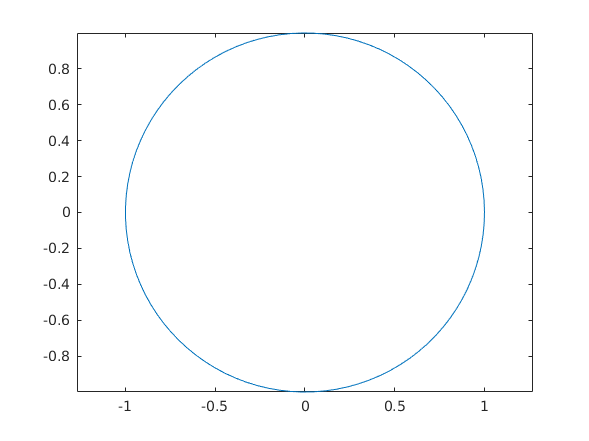

plot(x,y)
axis equal

As u increases from 0 to $2\pi$, the circle is traced out in counter-clockwise direction. The variable u can be interpreted as the angle from the x-axis to the current point on the circle.

**Exercise 1:** Look up the parametric equations that define an ellipse, and use the techniques developed here to visualize them. 

Solution: A quick browse of the internet shows that the parametric equations for an ellipse are


$$x = a \cos u, y = b \sin u, u \in [0,2\pi]$$


where a and b are parameters. Let's visualize the ellipse corresponding to a = 1 and b = 2

a = 1

a = 1

b = 2

b = 2

u = linspace(0,2*pi,100)

u =          0    0.0635    0.1269    0.1904    0.2539    0.3173    0.3808    0.4443    0.5077    0.5712    0.6347    0.6981    0.7616    0.8251    0.8885    0.9520    1.0155    1.0789    1.1424    1.2059    1.2693    1.3328    1.3963    1.4597    1.5232    1.5867    1.6501    1.7136    1.7771    1.8405


[x,y] = ellipse(u,a,b)

x =     1.0000    0.9980    0.9920    0.9819    0.9679    0.9501    0.9284    0.9029    0.8738    0.8413    0.8053    0.7660    0.7237    0.6785    0.6306    0.5801    0.5272    0.4723    0.4154    0.3569    0.2969    0.2358    0.1736    0.1108    0.0476   -0.0159   -0.0792   -0.1423   -0.2048   -0.2665


y =          0    0.1268    0.2532    0.3785    0.5023    0.6241    0.7433    0.8596    0.9724    1.0813    1.1858    1.2856    1.3802    1.4692    1.5523    1.6292    1.6995    1.7629    1.8193    1.8683    1.9098    1.9436    1.9696    1.9877    1.9977    1.9997    1.9937    1.9796    1.9576    1.9277


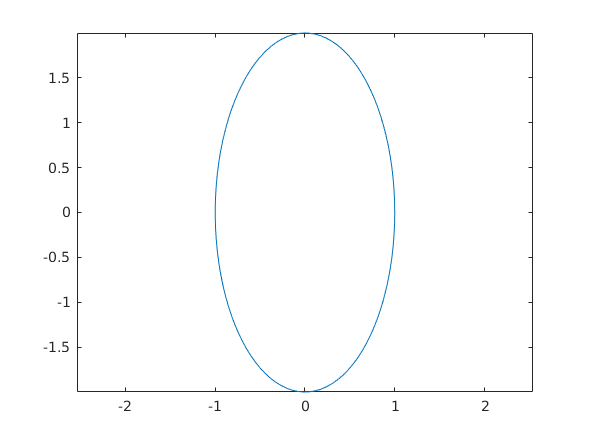

plot(x,y)
axis equal

**Exercise 2:** A helix in 3D is often defined using the parametric equations


$$x = a \cos u, y = a \sin u, z = bu$$


where both a and b are positive. Use **plot3** to visualize the helix with a = 1 and b = 2 over the domain $u \in [0,10]$.

a = 1

a = 1

b = 2

b = 2

u = linspace(0,10,100)

u =          0    0.1010    0.2020    0.3030    0.4040    0.5051    0.6061    0.7071    0.8081    0.9091    1.0101    1.1111    1.2121    1.3131    1.4141    1.5152    1.6162    1.7172    1.8182    1.9192    2.0202    2.1212    2.2222    2.3232    2.4242    2.5253    2.6263    2.7273    2.8283    2.9293


[x,y,z] = helix(u,a,b)

x =     1.0000    0.9949    0.9797    0.9544    0.9195    0.8752    0.8219    0.7603    0.6909    0.6145    0.5318    0.4437    0.3510    0.2548    0.1560    0.0556   -0.0453   -0.1459   -0.2449   -0.3414   -0.4344   -0.5230   -0.6063   -0.6834   -0.7536   -0.8160   -0.8701   -0.9154   -0.9513   -0.9775


y =          0    0.1008    0.2006    0.2984    0.3931    0.4839    0.5696    0.6496    0.7230    0.7889    0.8469    0.8962    0.9364    0.9670    0.9878    0.9985    0.9990    0.9893    0.9696    0.9399    0.9007    0.8523    0.7952    0.7300    0.6574    0.5781    0.4928    0.4026    0.3082    0.2107


z =          0    0.2020    0.4040    0.6061    0.8081    1.0101    1.2121    1.4141    1.6162    1.8182    2.0202    2.2222    2.4242    2.6263    2.8283    3.0303    3.2323    3.4343    3.6364    3.8384    4.0404    4.2424    4.4444    4.6465    4.8485    5.0505    5.2525    5.4545    5.6566    5.8586


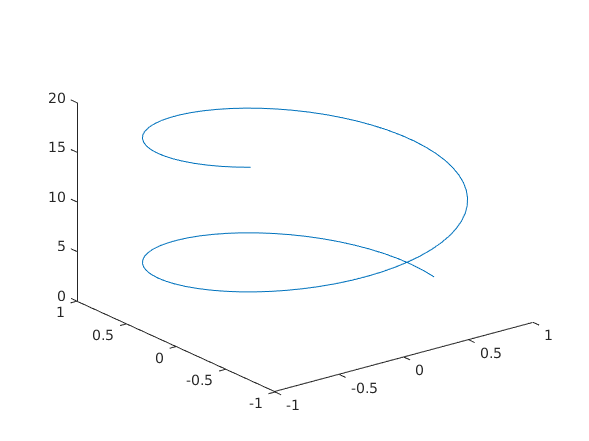

plot3(x,y,z)

## Function definitions

function [x,y] = circle(u)
    % circle   Computes the coordinates of a parametric circle
    x = cos(u);
    y = sin(u);
end

function [x,y] = ellipse(u,a,b)
    % ellipse Computes the coordinates of a parametric ellipse
    x = a*cos(u);
    y = b*sin(u);
end

function [x,y,z] = helix(u,a,b)
    % helix Computes the coordinates of a parametric helix
    x = a*cos(u);
    y = a*sin(u);
    z = b*u;
end